# Sistema de dos masas y tres resortes 

Aplicación importante a la Ingeniería de las ecuaciones diferenciales lineales homogéneas con coeficientes constantes.

[https://www.math24.net/mass-spring-system/](https://www.math24.net/mass-spring-system/)

Mechanical problems described by Newton’s laws of motion lead to systems of second-order equations and, if there is no dissipation, there are no first derivatives. Equations like this are called special second-order equations.

## Sin fricción 

Undamped vibration

n=2 masas y n+1=3 resortes

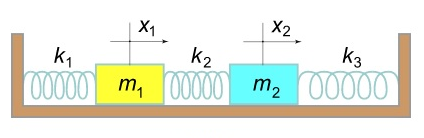


$$m_1 \;,m_{2\;} >0\;$$


$k_1 \;,k_2 \;,k_3 >0\;$  spring elasticity (stiffness)

$x_1 \left(t\right)\;,{\;x}_2 \left(t\right)$       displacement of $m_1 \;,m_2$ from equilibrium.

The displacement of each spring is measured relative to its own local coordinate system with an origin at the spring's equilibrium position. Positive is right and negative is left.

Ley de Hooke:  $F=-k\;x$                (fuerza de restauración)

La fuerza del resorte 1 sobre la masa 1 es $F_{11} =-k_1 \;x_1$

La fuerza del resorte 3 sobre la masa 2 es $F_{32} =-k_3 {\;x}_2$

La fuerza del resorte 2 sobre la masa 1 es $F_{21} =-k_2 \;\left(x_1 -x_2 \right)$

La fuerza del resorte 2 sobre la masa 2 es $F_{22} =-k_2 \;\left(x_2 -x_1 \right)=-F_{21}$

A mass attached to the left end of a spring of extension X and spring constant k experiences a horizontal force -kX, whereas a mass attached to the right end of the same spring experiences an equal and opposite force (http://farside.ph.utexas.edu/teaching/315/Waves/node18.html).

Segunda ley de Newton:  $F=m\;a=m\;\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }x$  


$$m_1 \;x_1^{\textrm{''}} =-k_1 x_1 -k_2 \left(x_1 -x_2 \right)$$



$$m_2 \;x_2^{\textrm{''}} =-k_2 \left(x_2 -x_1 \right)-k_3 x_2$$



$$x_1^{\textrm{''}} =\frac{-\left(k_1 +k_2 \right)}{m_1 }x_1 +\frac{k_2 }{m_1 }x_2$$



$$x_2^{\textrm{''}} =\frac{k_2 }{m_2 }x_1 +\frac{-\left(k_2 +k_3 \right)}{m_2 }x_2$$
 


$$x=\left\lbrack x_1 ;x_2 \right\rbrack$$



$$x^{\textrm{''}\;} =\left\lbrack \begin{array}{cc}
\frac{-\left(k_1 +k_2 \right)}{m_1 } & \frac{k_2 }{m_1 }\\
\frac{k_2 }{m_2 } & \frac{-\left(k_2 +k_3 \right)}{m_2 }
\end{array}\right\rbrack x=\textrm{Mx}$$
 


$$x^{\prime } =v$$



$$v^{\prime } =Mx$$


 
$$\textrm{xv}=\left\lbrack x;v\right\rbrack$$



$${\left(\textrm{xv}\right)}^{\prime } =\left\lbrack \begin{array}{cc}
0 & I\\
M & 0
\end{array}\right\rbrack \textrm{xv}=M_d \;\textrm{xv}$$
       

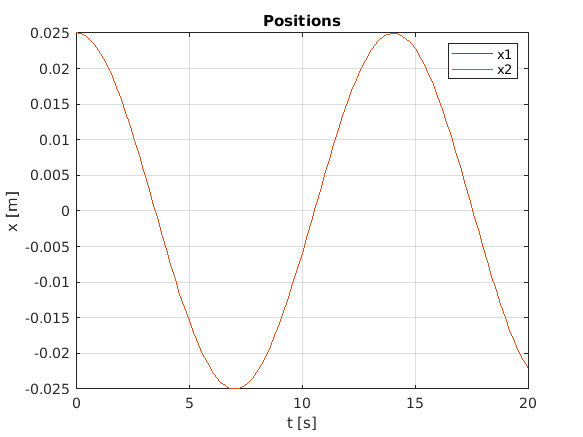

m = 0.05*ones(2,1);         % masas [kg]
k = 0.01*ones(3,1);         % constantes de los resortes
M = [-(k(1)+k(2))/m(1), k(2)/m(1);
    k(2)/m(2), -(k(2)+k(3))/m(2)];
Md = [zeros(2,2), eye(2); M, zeros(2,2)];

f = @(t,xv) Md*xv;

TS = 20;     % Tiempo que dura la simulación ([s])
N = 100;     % Número de pasos
h = TS/N;    % Tamaño del paso 

% Condiciones iniciales x1=-x2 o x1=x2; velocidades iniciales = 0
x0 = 0.025;
xv0 = [x0;x0;0;0];
[t,xv] = RK4(f, xv0, 0, TS, TS/N);
x = xv(1:2,:);
plot(t,x);
title('Positions')
legend('x1','x2')
xlabel('t [s]')
ylabel('x [m]')
grid on;

% En el caso x1=-x2 se observa que el período es aproximadamente de 8s

## Valores y vectores propios de M


$$x^{\textrm{''}} =\textrm{Mx}$$


Guess a solution: $x=ve^{\alpha t}$ 

then $x^{\textrm{''}} =\alpha^2 x$

and $\textrm{Mx}=\alpha^2 x\;$


$$\textrm{Mx}=\lambda x\;$$


[V,D] = eig(M)             % real eigenvectors  

V =     0.7071    0.7071
   -0.7071    0.7071


D =    -0.6000         0
         0   -0.2000


lambda = diag(D)           % negative eigenvalues for mass-spring models

lambda =    -0.6000
   -0.2000


% alfa^2 = lambda
alfa = sqrt(lambda)        % números imaginarios ( real(alfa) = [0;0] )

alfa =    0.0000 + 0.7746i
   0.0000 + 0.4472i


w = imag(alfa)             % angular frequency ([radianes/s])                         

w =     0.7746
    0.4472


T = (2*pi)./w               % two modes of oscillation, period [s    

T =     8.1116
   14.0496


## Solución analítica

%

## Conservación de energía

%